clear 
clc


addpath '.\INM'
addpath '.\SD'
addpath '.\FR'
addpath '.\functions'

load('forcing_terms.mat')
load('test_functions2.mat')
load('myFunctions.mat')

%Armijo
c1 = 1e-4;
rho = 0.5;
btmax = 50;
alpha0 = 1;

%Step for finite differences
h = 1e-8;

%Problem definition
n = 1000;
x0 = x16(n);
f = f16;
gradf = gf16;
Hessf = 0;

kmax = 50000;
tolgrad = 1.0E-6;
toldiffgrad = 1e-12;

% max number of iterations for the pcg
pcg_maxit = 200;

run_steepest = true;
run_fr = true;
run_newton = true;

%P5 -> Converges (with tolgrad or kmax easier)
%P13 -> Converges
%P14 -> Converge (con pcgmax=200,ci mette un botto)
%P23 

##     Run Steepest Descent

if run_steepest
    disp('***Steepest Descent: start***')
    tic
    [xk_sd, fk_sd, gradfk_norm_sd, k_sd, xseq_sd, btseq_sd, fseq_sd, gfseq_sd] = ... 
        steepest_desc_bt(x0, f, gradf, alpha0, kmax, tolgrad, c1, rho, btmax)
    
    disp('***Steepest Descent: finished')
    toc
    disp('***SD: results')
    disp('*******')
    disp(['xk: ', mat2str(xk_sd)])
    disp(['f(xk): ', mat2str(fk_sd)])
    disp(['gradf(xk): ', mat2str(gradfk_norm_sd)])
    disp(['N of iterations: ', num2str(k_sd), '/', num2str(kmax), ';'])
    
    disp('****')
else
    disp("SD Method not runned")
end

***Steepest Descent: start***


Iteration 1 gf_norm: 6895.447788
Iteration 2 gf_norm: 4851.936625
Iteration 3 gf_norm: 3867.562053
Iteration 4 gf_norm: 3275.755276
Iteration 5 gf_norm: 2838.055478
Iteration 6 gf_norm: 2520.298482
Iteration 7 gf_norm: 2286.881811
Iteration 8 gf_norm: 2108.842119
Iteration 9 gf_norm: 1971.551817
Iteration 10 gf_norm: 1863.733243
Iteration 11 gf_norm: 1778.259587
Iteration 12 gf_norm: 1709.773255
Iteration 13 gf_norm: 1654.476364
Iteration 14 gf_norm: 1609.495452
Iteration 15 gf_norm: 1572.676785
Iteration 16 gf_norm: 1542.363603
Iteration 17 gf_norm: 1517.276309
Iteration 18 gf_norm: 1496.413853
Iteration 19 gf_norm: 1478.987993
Iteration 20 gf_norm: 1464.372913
Iteration 21 gf_norm: 1452.068627
Iteration 22 gf_norm: 1441.673124
Iteration 23 gf_norm: 1432.861350
Iteration 24 gf_norm: 1425.369062
Iteration 25 gf_norm: 1418.980384
Iteration 26 gf_norm: 1413.518124
Iteration 27 gf_norm: 1408.836200
Iteration 28 gf_norm: 1404.813677
Iteration 29 gf_norm: 1401.350046
Iteration 30 gf_norm: 1

xk_sd =    -1.1071
   -0.7854
   -0.5880
   -0.4636
   -0.3805
   -0.3218
   -0.2783
   -0.2450
   -0.2187
   -0.1974


fk_sd = -427.4045

gradfk_norm_sd = 1.2157e-05

k_sd = 50000

xseq_sd =     0.9962    0.9925    0.9887    0.9849    0.9811    0.9774    0.9735    0.9697    0.9659    0.9621    0.9583    0.9544    0.9506    0.9467    0.9428    0.9390    0.9351    0.9312    0.9273    0.9234    0.9195    0.9155    0.9116    0.9077    0.9037    0.8998    0.8958    0.8919    0.8879    0.8839    0.8799    0.8759    0.8719    0.8679    0.8639    0.8599    0.8558    0.8518    0.8478    0.8437    0.8397    0.8356    0.8315    0.8275    0.8234    0.8193    0.8152    0.8111    0.8070    0.8029
    0.9946    0.9892    0.9838    0.9784    0.9730    0.9675    0.9621    0.9567    0.9512    0.9458    0.9403    0.9348    0.9294    0.9239    0.9184    0.9130    0.9075    0.9020    0.8965    0.8910    0.8855    0.8800    0.8745    0.8690    0.8635    0.8580    0.8525    0.8470    0.8415    0.8360    0.8305    0.8249    0.8194    0.8139    0.8084    0.8029    0.7973    0.7918    0.7863    0.7808    0.7752    0.7697    0.7642    0.7587    0.7531    0.7476    0.7421    0.7366    0.731

btseq_sd =      9     9     9     9     9     9     9     9     9     9     9     9     9     9     9     9     9     9     9     9     9     9     9     9     9     9     9     9     9     9     9     9     9     9     9     9     9     9     9     9     9     9     9     9     9     9     9     9     9     9


fseq_sd = 1.0e+04 *

    3.8776    1.7334    1.0221    0.7062    0.5110    0.3875    0.3082    0.2530    0.2139    0.1850    0.1633    0.1466    0.1336    0.1232    0.1149    0.1082    0.1026    0.0980    0.0942    0.0910    0.0883    0.0860    0.0840    0.0823    0.0809    0.0796    0.0785    0.0775    0.0766    0.0759    0.0752    0.0746    0.0741    0.0736    0.0732    0.0728    0.0725    0.0722    0.0719    0.0717    0.0714    0.0712    0.0710    0.0708    0.0707    0.0705    0.0704    0.0702    0.0701    0.0700


gfseq_sd = 1.0e+03 *

    6.8954    4.8519    3.8676    3.2758    2.8381    2.5203    2.2869    2.1088    1.9716    1.8637    1.7783    1.7098    1.6545    1.6095    1.5727    1.5424    1.5173    1.4964    1.4790    1.4644    1.4521    1.4417    1.4329    1.4254    1.4190    1.4135    1.4088    1.4048    1.4014    1.3984    1.3958    1.3935    1.3916    1.3899    1.3884    1.3872    1.3860    1.3851    1.3842    1.3835    1.3828    1.3822    1.3817    1.3813    1.3809    1.3805    1.3802    1.3800    1.3797    1.3795


***Steepest Descent: finished


Elapsed time is 94.256111 seconds.


***SD: results


*******


xk: [-1.10714646544492;-0.78539812843736;-0.588002603360675;-0.463647609000229;-0.380506377112363;-0.321750554396641;-0.278299659005111;-0.244978663126864;-0.218668945873942;-0.197395559849881;-0.179853499792479;-0.165148677414627;-0.152649328395265;-0.141897054604164;-0.132551532296674;-0.124354994546762;-0.117108744566864;-0.110657221173896;-0.104876938730234;-0.0996686524911622;-0.0949517063427563;-0.0906598872007452;-0.0867383386759852;-0.0831412318884413;-0.0798299857122374;-0.076771891269778;-0.0739390376579403;-0.0713074647852904;-0.0688564893010447;-0.0665681637758239;-0.0644268394255536;-0.0624188099959574;-0.0605320197821072;-0.0587558227157229;-0.0570807824062648;-0.055498505245717;-0.0540015003759683;-0.0525830616109418;-0.0512371674034189;-0.0499583957219429;-0.0487418513099317;-0.0475831032769836;-0.046478131351003;-0.0454232794215771;-0.0444152152469109;-0.0434508953915309;-0.0425275346197842;-0.0416425790985885;-0.0407936828678654;-0.0399786871232901;-0.0391956019270547

f(xk): -427.404476374843


gradf(xk): 1.2157322285598e-05


N of iterations: 50000/50000;


****


**Run FR**

if run_fr
    kmax = 50000
    disp('***FR: start***')
    tic
    [xk, fk, gradfk_norm, k_fr, xseq_fr, btseq_fr, fseq_fr, gfseq_fr] = fletcher_reeves(x0, f, gradf, alpha0, kmax, tolgrad, c1, rho, btmax)
    
    disp('***FR: finished')
    toc
    disp('***FR: results')
    disp('*******')
    disp(['xk: ', mat2str(xk)])
    disp(['f(xk): ', mat2str(fk)])
    disp(['gradf(xk): ', mat2str(gradfk_norm)])
    disp(['N of iterations: ', num2str(k_fr), '/', num2str(kmax), ';'])
    
    disp('****')
else
    disp("FR Method not runned")
end

kmax = 50000

***FR: start***


Iteration 1 gf_norm: 6895.447788
Iteration 2 gf_norm: 2672.436178
Iteration 3 gf_norm: 1516.816481
Iteration 4 gf_norm: 1216.833149
Iteration 5 gf_norm: 771.975499
Iteration 6 gf_norm: 394.900864
Iteration 7 gf_norm: 659.994198
Iteration 8 gf_norm: 655.288900
Iteration 9 gf_norm: 529.135395
Iteration 10 gf_norm: 429.604526
Iteration 11 gf_norm: 338.005049
Iteration 12 gf_norm: 411.099133
Iteration 13 gf_norm: 351.311310
Iteration 14 gf_norm: 337.134961
Iteration 15 gf_norm: 251.276009
Iteration 16 gf_norm: 220.077427
Iteration 17 gf_norm: 270.534703
Iteration 18 gf_norm: 246.880664
Iteration 19 gf_norm: 254.008226
Iteration 20 gf_norm: 273.178900
Iteration 21 gf_norm: 217.759957
Iteration 22 gf_norm: 185.429005
Iteration 23 gf_norm: 218.257376
Iteration 24 gf_norm: 212.092059
Iteration 25 gf_norm: 175.730430
Iteration 26 gf_norm: 168.172885
Iteration 27 gf_norm: 193.069220
Iteration 28 gf_norm: 189.236397
Iteration 29 gf_norm: 158.034093
Iteration 30 gf_norm: 174.315163
Iteration 31 gf

xk =    -1.1071
   -0.7854
   -0.5880
   -0.4636
   -0.3805
   -0.3218
   -0.2783
   -0.2450
   -0.2187
   -0.1974


fk = -427.4045

gradfk_norm = 7.3911e-05

k_fr = 50000

xseq_fr =     0.9962    0.9917    0.9873    0.9821    0.9749    0.9682    0.9571    0.9522    0.9407    0.9313    0.9231    0.9091    0.8968    0.8858    0.8736    0.8649    0.8475    0.8399    0.8252    0.8076    0.7964    0.7883    0.7744    0.7637    0.7526    0.7440    0.7260    0.7228    0.7093    0.6989    0.6851    0.6697    0.6580    0.6477    0.6362    0.6259    0.6184    0.6025    0.5950    0.5784    0.5661    0.5520    0.5346    0.5195    0.5084    0.4959    0.4814    0.4703    0.4550    0.4477
    0.9946    0.9881    0.9817    0.9743    0.9640    0.9545    0.9386    0.9317    0.9153    0.9019    0.8903    0.8705    0.8530    0.8376    0.8206    0.8083    0.7841    0.7735    0.7532    0.7289    0.7135    0.7023    0.6834    0.6689    0.6538    0.6421    0.6179    0.6136    0.5956    0.5817    0.5634    0.5430    0.5276    0.5142    0.4992    0.4859    0.4762    0.4559    0.4464    0.4254    0.4099    0.3922    0.3704    0.3517    0.3380    0.3226    0.3050    0.2916    0.273

btseq_fr =      9     9     9     9     9     9     8    11    10    10    10     9    10    10    10    10     9    11    10    10    11    11    10    11    11    11    10    13    11    11    11    11    11    11    11    11    11    10    12    11    11    11    11    11    11    11    11    11    10    12


fseq_fr = 1.0e+04 *

    3.8776    0.8051    0.2775    0.1446    0.0592    0.0106    0.0060    0.0052   -0.0074   -0.0156   -0.0205   -0.0219   -0.0229   -0.0258   -0.0298   -0.0319   -0.0326   -0.0331   -0.0342   -0.0342   -0.0349   -0.0358   -0.0366   -0.0369   -0.0375   -0.0380   -0.0380   -0.0380   -0.0385   -0.0386   -0.0390   -0.0395   -0.0397   -0.0400   -0.0403   -0.0405   -0.0407   -0.0407   -0.0408   -0.0409   -0.0409   -0.0410   -0.0412   -0.0412   -0.0413   -0.0414   -0.0416   -0.0417   -0.0417   -0.0417


gfseq_fr = 1.0e+03 *

    6.8954    2.6724    1.5168    1.2168    0.7720    0.3949    0.6600    0.6553    0.5291    0.4296    0.3380    0.4111    0.3513    0.3371    0.2513    0.2201    0.2705    0.2469    0.2540    0.2732    0.2178    0.1854    0.2183    0.2121    0.1757    0.1682    0.1931    0.1892    0.1580    0.1743    0.1780    0.1479    0.1311    0.1319    0.1183    0.0937    0.0894    0.1184    0.1203    0.0989    0.1018    0.1095    0.0980    0.0799    0.0813    0.0839    0.0696    0.0537    0.0715    0.0769


***FR: finished


Elapsed time is 159.612683 seconds.


***FR: results


*******


xk: [-1.10714924639302;-0.785402545081882;-0.588001842689599;-0.463647054066634;-0.38050521116952;-0.321750169229409;-0.278299412830851;-0.2449784072564;-0.218668992751171;-0.197395451158382;-0.179853285236107;-0.165148573334311;-0.152649077966918;-0.141897155952271;-0.132551434351282;-0.124354741596112;-0.117108858944541;-0.110656777531719;-0.104876999492333;-0.0996685472359057;-0.094951874872339;-0.0906599852311008;-0.0867380147092288;-0.0831412471945723;-0.0798299790169198;-0.0767718212329913;-0.0739391544631886;-0.0713074792560147;-0.0688564740125242;-0.0665682240049987;-0.0644268423219738;-0.0624188002683704;-0.0605320170324513;-0.0587558165096209;-0.0570808362780624;-0.0554985325595164;-0.0540014399009398;-0.0525830423916013;-0.0512371929069543;-0.0499583661411858;-0.0487418347477854;-0.047583139174726;-0.0464781014816259;-0.0454232160787627;-0.0444152820817784;-0.0434510220153024;-0.0425275326999668;-0.0416425216632686;-0.0407937496663448;-0.0399788018552889;-0.0391955852319318;

f(xk): -427.404476374803


gradf(xk): 7.39105140117526e-05


N of iterations: 50000/50000;


****


### **Run the Newton**

if run_newton
    kmax = 50
    % fterms = @(gradf, x, k) 0.5;
    % fterms = @(gradfk, k) min(0.5, sqrt(norm(gradfk)));
    fterms = @(gradfk, k) min(0.5, norm(gradfk));
    
    % options for finite differences
    FDgrad = 'c';
    FDHess = 'fw';
    
    disp('***IN. NEWTON F.D. options***')
    disp(['FDgrad: ', FDgrad])
    disp(['FDHess: ', FDHess])
    
    disp('***Newton: start***')
    tic
    [xk, fk, gradfk_norm, k_inm, xseq, btseq, fseq, gfseq] = ...
    innewton_general(x0, f, gradf, Hessf, kmax, ...
    tolgrad, toldiffgrad, c1, rho, btmax, FDgrad, FDHess, h, fterms, pcg_maxit)
    
    disp('***IN. newton: finished')
    toc
    disp('***newton: results')
    disp('*******')
    disp(['xk: ', mat2str(xk)])
    disp(['f(xk): ', mat2str(fk)])
    disp(['gradf(xk): ', mat2str(gradfk_norm)])
    disp(['N of iterations: ', num2str(k_inm), '/', num2str(kmax), ';'])
    
    disp('****')
else
    disp("Newton Method not runned")
end

kmax = 50

***IN. NEWTON F.D. options***


FDgrad: c


FDHess: fw


***Newton: start***


 
Hessian non-PD
pcg converged at iteration 1 to a solution with relative residual 0.26.
gradfk_norm: 11157.461432 
Hessian non-PD
pcg converged at iteration 1 to a solution with relative residual 0.16.
gradfk_norm: 5112.310618 
Hessian non-PD
pcg converged at iteration 1 to a solution with relative residual 0.19.
gradfk_norm: 1217.332221 
Hessian non-PD
pcg converged at iteration 3 to a solution with relative residual 0.33.
gradfk_norm: 405.769275 
Hessian non-PD
pcg converged at iteration 4 to a solution with relative residual 0.38.
gradfk_norm: 152.419415 
Hessian non-PD
pcg converged at iteration 6 to a solution with relative residual 0.48.
gradfk_norm: 73.043918 
Hessian non-PD
pcg converged at iteration 4 to a solution with relative residual 0.46.
gradfk_norm: 33.359591 
Hessian non-PD
pcg converged at iteration 9 to a solution with relative residual 0.49.
gradfk_norm: 16.159627 
Hessian PD
pcg converged at iteration 70 to a solution with relative residual 0.46.
gradfk_norm: 8.08

xk =   -19.9567
   -0.7854
   -0.5880
   -0.4637
   -0.3805
   -0.3218
   -0.2783
   -0.2450
   -0.2187
   -0.1974


fk = -427.4045

gradfk_norm = 1.8657e-04

k_inm = 50

xseq =     0.9952    0.9918    0.9894    0.9710    0.9260    0.8246    0.7827    0.4194  -21.4838  -18.6418  -20.3796  -20.0663  -20.0325  -20.0209  -19.9623  -19.9580  -19.9567  -19.9567  -19.9567  -19.9567  -19.9567  -19.9567  -19.9567  -19.9567  -19.9567  -19.9567  -19.9567  -19.9567  -19.9567  -19.9567  -19.9567  -19.9567  -19.9567  -19.9567  -19.9567  -19.9567  -19.9567  -19.9567  -19.9567  -19.9567  -19.9567  -19.9567  -19.9567  -19.9567  -19.9567  -19.9567  -19.9567  -19.9567  -19.9567  -19.9567
    0.9931    0.9882    0.9848    0.9585    0.8944    0.7529    0.6964    0.2249   -1.6413   -1.4899   -0.9303   -0.8001   -0.7944   -0.7927   -0.7846   -0.7853   -0.7854   -0.7854   -0.7854   -0.7854   -0.7854   -0.7854   -0.7854   -0.7854   -0.7854   -0.7854   -0.7854   -0.7854   -0.7854   -0.7854   -0.7854   -0.7854   -0.7854   -0.7854   -0.7854   -0.7854   -0.7854   -0.7854   -0.7854   -0.7854   -0.7854   -0.7854   -0.7854   -0.7854   -0.7854   -0.7854   -0.7854   -0.7854   -0.7854  

btseq =      0     0     0     0     0     0     0     0     0     3     1     0     0     0     0     0     0    13    20    12    23    25    30    32    33    13    29    32    35    35    36    37    37    37    37    37    32    34    22    28    35    35    35    32    15    30    32    16    20    18


fseq = 1.0e+04 *

    9.2842    1.8290    0.3181    0.0215   -0.0298   -0.0393   -0.0406   -0.0421   -0.0424   -0.0425   -0.0427   -0.0427   -0.0427   -0.0427   -0.0427   -0.0427   -0.0427   -0.0427   -0.0427   -0.0427   -0.0427   -0.0427   -0.0427   -0.0427   -0.0427   -0.0427   -0.0427   -0.0427   -0.0427   -0.0427   -0.0427   -0.0427   -0.0427   -0.0427   -0.0427   -0.0427   -0.0427   -0.0427   -0.0427   -0.0427   -0.0427   -0.0427   -0.0427   -0.0427   -0.0427   -0.0427   -0.0427   -0.0427   -0.0427   -0.0427


gfseq = 1.0e+04 *

    1.1157    0.5112    0.1217    0.0406    0.0152    0.0073    0.0033    0.0016    0.0008    0.0007    0.0004    0.0002    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


***IN. newton: finished


Elapsed time is 6185.688013 seconds.


***newton: results


*******


xk: [-19.9567065404789;-0.785402610973667;-0.588004519664798;-0.463654542345651;-0.380503486650934;-0.32175139862382;-0.278299334432097;-0.244978202248406;-0.218667863633461;-0.197393358693068;-0.179853201928332;-0.165148335076554;-0.152647903468803;-0.141896340479882;-0.132551616145396;-0.124355486163442;-0.117108833291438;-0.11065707347495;-0.104877079947859;-0.0996686632252499;-0.0949518820292242;-0.0906601793210309;-0.0867387461950788;-0.083141431999211;-0.0798300960226783;-0.0767719025960267;-0.073938937089027;-0.0713073916907829;-0.0688565748787665;-0.0665684340940328;-0.0644271722719536;-0.0624190739244291;-0.0605320262427839;-0.0587556335193667;-0.0570808612356215;-0.0554987236392647;-0.0540016781931828;-0.0525831073790722;-0.0512371021129123;-0.0499582085961872;-0.048741797527609;-0.0475831451686736;-0.0464784307009322;-0.0454235642779931;-0.0444154828993281;-0.0434508810226086;-0.042527477791615;-0.0416426022641057;-0.040793684573948;-0.0399787741620968;-0.0391956347323373;-0

f(xk): -427.404476374575


gradf(xk): 0.000186568552547627


N of iterations: 50/50;


****


disp('===========================================================================================================================================================================')

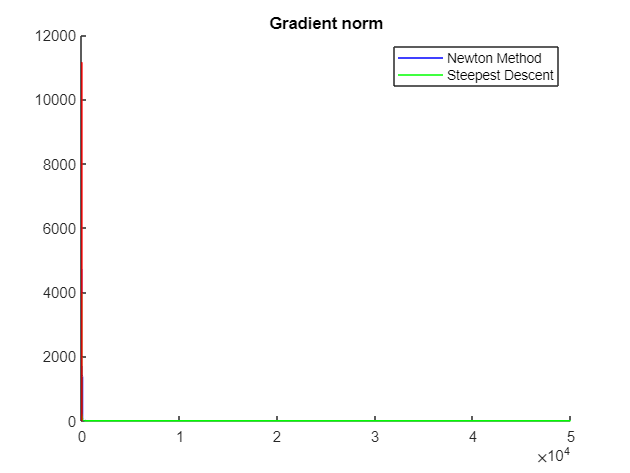

figure(1);
hold on;
title("Gradient norm")
plot(linspace(0,k_sd,k_sd), gfseq_sd, "b")
plot(linspace(0,k_fr,k_fr), gfseq_fr, "g")
plot(linspace(0,k_inm,k_inm), gfseq, "r")
legend(["Steepest Descent", "Fletcher Reeves", "Newton Method"])
hold off;

figure(2);
hold on;
title("Funcion value")
plot(linspace(0,k_sd,k_sd), fseq_sd, "b")
plot(linspace(0,k_fr,k_fr), gfseq_fr, "g")
plot(linspace(0,k_inm,k_inm), fseq, "r")

plot(k_sd, fseq_sd(k_sd), "*b")
legend("Newton Method","NM Stop", "Steepest Descent", "SD Stop")
hold off;

% disp_int = [-1 1];
% 
% f1_meshgrid = @(X,Y)reshape(f([X(:),Y(:)]'),size(X));
% fcontour(f1_meshgrid, disp_int, 'Fill','on');
% hold on
% h = plot(xseq(1,:), xseq(2,:), '-*r', 'linewidth', 1, 'markersize', 5);
% hold off

% % creation of meshgrid for the contour-plot
% [X1, Y1] = meshgrid(linspace(-2, 2, 500), linspace(-2, 2, 500));
% 
% % computation of the values of f for each point of the mesh
% % Z1 = (1-X1).^2 + 100 * (Y1-X1.^2).^2;
% 
% % Plots
% 
% % simple plot
% fig1_n = figure();
% 
% % contour plot with curve levels for each point in xseq
% % [C1, ~] = contour(X1, Y1, Z1, [1, 10, 50, 100:1000:9000]);
% 
% hold on
% % plot of the points in xseq
% plot([x0(1) xseq(1, :)], [x0(2) xseq(2, :)], '-*', color="r")
% 
% hold off
% title('Inexact Newton')
